# **Procesamiento de Imagenes Digitales**

# **Taller 8**

Lea la imagen `"trui.tif"` . 

I = imread('trui.tif');

Visualice la imagen en la `figura 1`. 

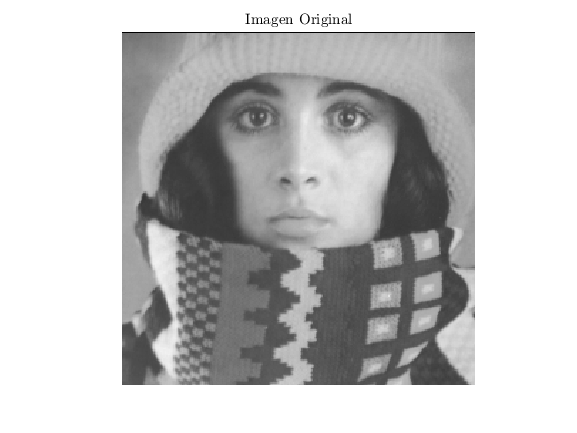

figure(1);
imshow(I);title('Imagen Original','Interpreter','Latex');

Calcule la transformada de Fourier centrada de la imagen. En otra variable aplique un ajuste logaritmico de contraste para visualizar el espectro de Fourier como imagen en la `figura 2`.

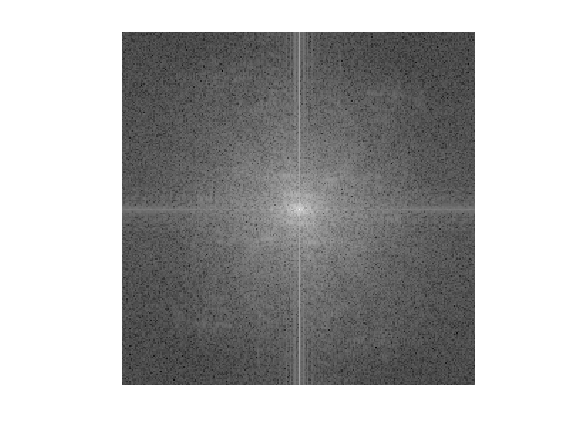

F = fftshift(fft2(I));
FL = im2uint8(mat2gray(log(1+double(abs(F)))));
figure(2);
imshow(FL);

Calcule la función optica de transferencia (OTF) centrada a partir de la respuesta al impuslo (PSF) dada por la siguiente expresión:


$$h(x,y)=e^{\frac{-(U-M/2)^{2}}{48}} e^{\frac{-(V-N/2)^{2}}{48}}}$$


y visualice su parte` real` en la `figura 3`. (utiice la función` psf2otf(h,size(h))`)

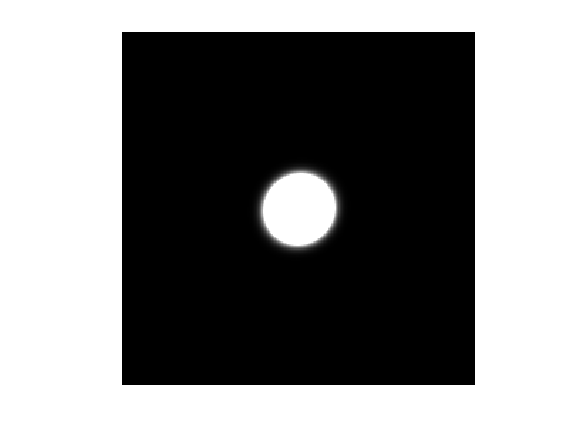

[M,N] = size(I);
[U,V] = meshgrid(1:M,1:N);
h = exp((-(U-M./2).^2)./48).*exp((-(V-N./2).^2)./48);
H = fftshift(psf2otf(h,size(h)));
figure(3);
imshow(real(H));

Genere la imagen Blurred a partir de, 


$$I_{blurred}=\Im^{-1}|F(u,v)H(u,v)|$$


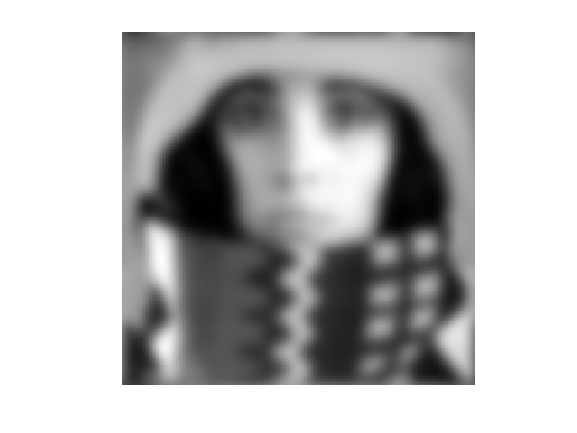

IBlurred = abs(ifft2(F.*H));
IBlurred = im2uint8(mat2gray(real(IBlurred)));
figure(4);
imshow(IBlurred);

Realice la operación de restauración de la imagen, utilizando unicamente el indice de las matrices que corresponden con el valor $indices=H>1e^{exp}$ en donde $exp$ es el orden o valor del exponente que presenta el valor minimo de la parte real de $H(u,v)$.

min = real(min(H(:)));

Array indices must be positive integers or logical values.

e = real(floor(log10(min)));
Ind = find(H>exp(e));
FH = F.*H;
F = zeros(size(FH));
F(Ind) = FH(Ind)./IBlurred(FH);
Ires = ifft2(fftshift(Frest));
Ires = im2uint8(mat2gray(real(Ires)));
figure(5);
imshow(Ires);